# **MATLAB Live Script that loads in the NIST electron IMFP data and saves it all as a concise MATLAB data structure**

The **Electron Inelastic Mean Free Path Database (eIMFPD) **local MATLAB reference file 'eIMFPD_PCC.mat' is created and saved here.

- You do not need to run this program, as the database will always be up-to-date with all released versions.

- This MATLAB Live Script is saved and stored here for future reference and in case of any future updates to the eIMFPD database.

The theoretical / optical data is taken from the NIST Electron Inelastic-Mean-Free-Path Database, which can be found here; [http://dx.doi.org/10.18434/T48C78](http://dx.doi.org/10.18434/T48C78).

**(1)     :    Defining all of the variables**

close all; clear all;
% -- Defining the elements whose photoionisation cross-sections we have
ATOM_SYMB = {...
    'H','He',...
    'Li','Be','B','C','N','O','F','Ne',...
    'Na','Mg','Al','Si','P','S','Cl','Ar',...
    'K','Ca','Sc','Ti','V','Cr','Mn','Fe','Co','Ni','Cu','Zn','Ga','Ge','As','Se','Br','Kr',...
    'Rb','Sr','Y','Zr','Nb','Mo','Tc','Ru','Rh','Pd','Ag','Cd','In','Sn','Sb','Te','I','Xe',...
    'Cs','Ba','La','Ce','Pr','Nd','Pm','Sm','Eu','Gd','Tb','Dy','Ho','Er','Tm','Yb','Lu','Hf','Ta','W','Re','Os','Ir','Pt','Au','Hg','Tl','Pb','Bi','Po','At','Rn',...
    'Fr','Ra','Ac','Th','Pa','U'};
% -- Defining the Z number for each one of these elements
ATOM_ZNUM = 1:length(ATOM_SYMB);

**(2)     :    Iterating through all the data-files and storing the data**

% -- Path to the folders
output_path = "D:\OneDrive\2021 - PostDoc (PSI)\Github\ADRESSTools\ADRESSTools_Basil\MaterialsDatabase_PCC\Electron Inelastic Mean Free Path Database (eIMFPD)\";
path_name   = output_path + "eIMFPD_OpticalData_NIST\";
% -- Extracting all the filenames for the photoionisation data
file_names = dir(path_name);
file_names = {file_names(~[file_names.isdir]).name};
% -- Filing through all the elements to isolate each element
for i = ATOM_ZNUM
    % --- Finding the index number for the element
    findx           = find(contains(file_names, "_"+string(ATOM_SYMB{i})+"_"));
    selected_names  = file_names(findx);
    eIMFP_FileNames{i} = selected_names;
end
eIMFP_Data      = {};
% -- Loading in all the data for each text file
for i = ATOM_ZNUM
    ke_dat      = [];
    imfp_dat    = [];
    for j = 1:length(eIMFP_FileNames{i})
        % -- Loading in all of the data
        data_00     = readtable(string(path_name) + string(eIMFP_FileNames{i}{j}));
        % -- Modify variable names
        data_00.Properties.VariableNames{1} = 'Energy';
        data_00.Properties.VariableNames{2} = 'IMFP';
        % -- Finding the first NaN value to crop to
        indx    = max(find(isnan(data_00.Energy)));
        ke_dat      = data_00.Energy(indx+1:end);
        imfp_dat    = data_00.IMFP(indx+1:end);
        % -- Storing the data into a cell array
        eIMFP_Data{i}{j} = [ke_dat, imfp_dat];
    end
    
end
% -- Finding the total number of text-files laoded for each element
eIMFP_Length    = [];
for i = ATOM_ZNUM; eIMFP_Length(i) = length(eIMFP_Data{i}); end

**(3)     :    Interpolating the eIMFP data onto a consistent domain**

% -- Loading in all the data for each text file
eIMFP_DataInterp = {};
for i = 1:length(eIMFP_Data)
    ke_dat      = [];
    imfp_dat    = [];
    for j = 1:length(eIMFP_Data{i})
        % -- Loading in the original data
        ke_dat      = eIMFP_Data{i}{j}(:,1);   % -- Electron Kinetic Energy
        imfp_dat    = eIMFP_Data{i}{j}(:,2);   % -- Inelastic Mean Free Path
        % -- Storing the data into a cell array
        ek_V    = linspace(min(ke_dat(:)), max(ke_dat(:)), 2e3);
        imfp_V  = interp1(ke_dat, imfp_dat, ek_V, 'spline');
        % -- Appending the interpolated data into a cell array
        eIMFP_DataInterp{i}{j} = [ek_V', imfp_V'];
    end
end

**(4)     :    Create a table for each element that sumamrises all of the eIMFP data**

for i = 1:length(eIMFP_Data)
    eIMFP_Table{i}  = table();
    for j = 1:length(eIMFP_Data{i})
        ek_name     = "ek_" + string(j);
        imfp_name   = "imfp_" + string(j);
        eIMFP_Table{i}.(ek_name)    = eIMFP_DataInterp{i}{j}(:,1);
        eIMFP_Table{i}.(imfp_name)  = eIMFP_DataInterp{i}{j}(:,2);
    end
end

**(5)     :    Storing the Electron Inelastic Mean Free Path (eIMFP) Data as a MATLAB structure for future reference**

eIMFPD_PCC                 = struct();
eIMFPD_PCC.ATOM_SYMB       = ATOM_SYMB;             % Atomic symbols used
eIMFPD_PCC.ATOM_ZNUM       = ATOM_ZNUM;             % Atomic Z number for each one of these elements
eIMFPD_PCC.FileNames       = eIMFP_FileNames;       % Cell-array of all the text file names
eIMFPD_PCC.Length          = eIMFP_Length;          % Array where; {Atom Z number}(total number of files used)
eIMFPD_PCC.Data            = eIMFP_Data;            % Cell-array where; {Atom Z number}{File Index}(electron kinetic energy [eV], imfp [Ang])
eIMFPD_PCC.DataInt         = eIMFP_DataInterp;      % Cell-array where; {Atom Z number}{Core-level}(electron kinetic energy [eV], imfp [Ang])
eIMFPD_PCC.DataTable       = eIMFP_Table;           % MATLAB Table where; {Atom Z number}
save(char(output_path + "eIMFPD_PCC"), 'eIMFPD_PCC', '-v7.3');

# **Example: Extracting the electron IMFP for any element and plotting their data**

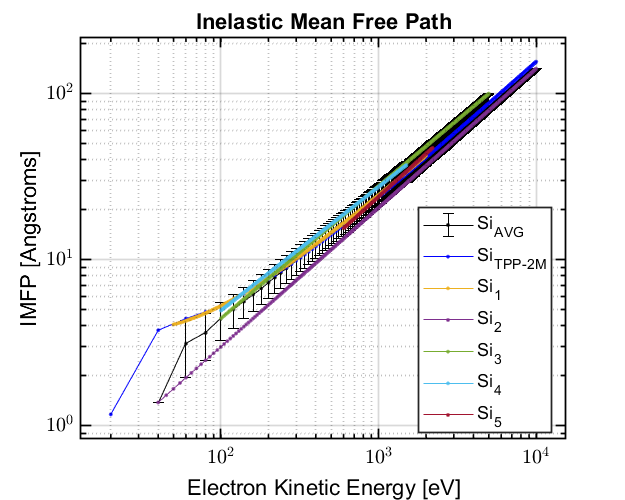

element = 'Si';
% Use the 'get_eIMFPD_props()' function to extract all eIMFP experimental data
[ke_dat, imfp_dat]      = get_eimfpd_props(element);
% Use the 'imfp_optical()' function to extract the best estimate from the experimental optical data
ke_avg                  = linspace(20, 1e4, 500);
[imfp_avg, dimfp_avg]   = imfp_optical(ke_avg, element);
% Use the 'imfp_tpp2m_mpd()' function to extract the IMFP based on the theoretical TPP-2M formalism
imfp_tpp2m              = imfp_tpp2m_mpd(ke_avg, element);
% Plotting the output data to check for correct values
% -- Initialising the figure
pp = plot_props();
fig = figure(); hold on;
fig.Position(3) = pp.fig5x4(1);
fig.Position(4) = pp.fig5x4(2);
% -- Plotting the best estimate of the IMFP first
errorbar(ke_avg, imfp_avg, dimfp_avg, dimfp_avg, 'k.-');
tit_label{1} = char(sprintf("%s_{AVG}",element));
% -- Plotting the best estimate of the IMFP first
plot(ke_avg, imfp_tpp2m, 'b.-');
tit_label{2} = char(sprintf("%s_{TPP-2M}",element));
% -- Plotting the electron kinetic energy vs imfp
for i = 1:size(ke_dat,2)
    plot(ke_dat(:,i), imfp_dat(:,i), '.-');
    tit_label{i+2} = char(sprintf("%s_%i",element,i));
end
legend(tit_label, 'location', 'best');
title('Inelastic Mean Free Path');
xlabel('Electron Kinetic Energy [eV]');
ylabel('IMFP [Angstroms]');
axis padded; loglog_props(); grid on;